
clear;

csvFolderName = "StockVibro";
clockTimeLimit = 25; % 体験時間 (s)
stopTime = clockTimeLimit;
stopTable = table(stopTime);
writetable(stopTable, csvFolderName + '\' + "stop.csv");

Stock Left

dt = 0.01;
T = 10;
xLimit = 100; % 単位 (mm)
clockTime = [
    (0:dt:T-dt)';
    (T:dt:2*T-dt)';
    ]

clockTime =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


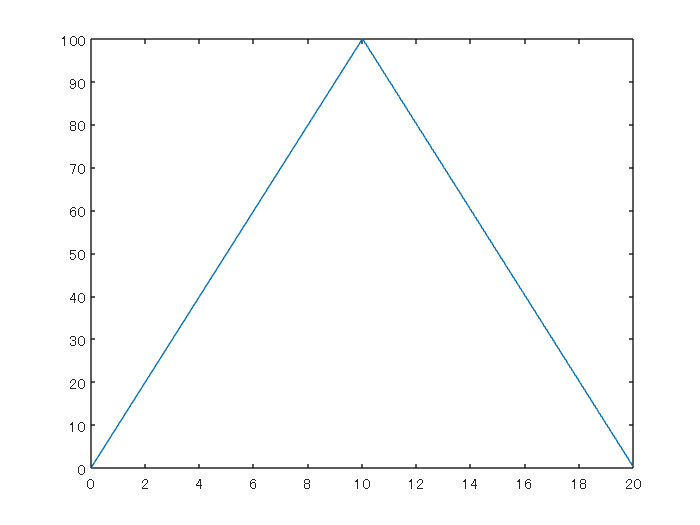


x = [
    xLimit * (0:dt:T-dt)'/T;
    -xLimit * ((T:dt:2*T-dt)' - T)/T + xLimit;
    ];
figure;
plot(clockTime, x);

StockVibroCSV = table(clockTime, x)

StockVibroCSV = 2000×2 table
    clockTime     x 
    _________    ___

         0         0
      0.01       0.1
      0.02       0.2
      0.03       0.3
      0.04       0.4
      0.05       0.5
      0.06       0.6
      0.07       0.7
      0.08       0.8
      0.09       0.9
       0.1         1
      0.11       1.1
      0.12       1.2
      0.13       1.3
      0.14       1.4
      0.15       1.5


writetable(StockVibroCSV, csvFolderName + '\' + "StockVibro.csv");

function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end